# Dataset pre-processing

% Merge Weather dataset and Electricity peak demand.
% With GDP, Normalize -> Normalize.mat

clear; clc;

load('peak_demand.mat')
load('temperature_merged.mat')

Dataset = horzcat(peak_elec,temp_low_high);

save('Dataset.mat','Dataset')

전력거래소로부터 얻어온 2011년 1월 1일부터 2018년 12월 31일까지의 일일 최대전력수요량과 동일 기간동안의 일일 최저기온, 최고기온 정보를 병합하여 배열로 만든다.

## Normalize dataset

Normalized_dataset = Dataset;

gdp_2011 = 1332681;
gdp_2012 = 1377457;
gdp_2013 = 1429445;
gdp_2014 = 1486079;
gdp_2015 = 1564124;
gdp_2016 = 1641786;
gdp_2017 = 1730399;
gdp_2018 = 1782269;

for i=1:size(Dataset,1)
    if Normalized_dataset(i,1) == 2011
        Normalized_dataset(i,4) = Normalized_dataset(i,4) * gdp_2018 / gdp_2011;
    elseif Normalized_dataset(i,1) == 2012
        Normalized_dataset(i,4) = Normalized_dataset(i,4) * gdp_2018 / gdp_2012;
    elseif Normalized_dataset(i,1) == 2013
        Normalized_dataset(i,4) = Normalized_dataset(i,4) * gdp_2018 / gdp_2013;
    elseif Normalized_dataset(i,1) == 2014
        Normalized_dataset(i,4) =Normalized_dataset(i,4) * gdp_2018 / gdp_2014;
    elseif Normalized_dataset(i,1) == 2015
        Normalized_dataset(i,4) = Normalized_dataset(i,4) * gdp_2018 / gdp_2015;
    elseif Normalized_dataset(i,1) == 2016
        Normalized_dataset(i,4) =Normalized_dataset(i,4) * gdp_2018 / gdp_2016;
    elseif Normalized_dataset(i,1) == 2017
        Normalized_dataset(i,4) =Normalized_dataset(i,4) * gdp_2018 / gdp_2017;
    elseif Normalized_dataset(i,1) == 2018
        Normalized_dataset(i,4) =Normalized_dataset(i,4) * gdp_2018 / gdp_2018;
    end
end

save('normalized_dataset.mat', 'Normalized_dataset')

# Split Dataset

% clear; clc;
% 
% tmp = [];
% tmp_norm = [];
% 
% for compare_year=2011:2018
%     load('merged_data.mat')
%     merged = merged(find(merged(:,1) == compare_year),:);
%     
%     tmp(:,:,end+1) = merged;
%     
%     filename = [ "merged_" + num2str(compare_year) + ".mat" ];
%     save(filename,'merged')
% end
% 
% for compare_year=2011:2018
%     load('normalized_data.mat')
%     normalized_data = normalized_data(find(normalized_data(:,1) == compare_year),:);
%     
%     tmp_norm(:,:,end+1) = normalized_data;
%     
%     filename = [ "normalized_" + num2str(compare_year) + ".mat" ];
%     save(filename,'normalized_data')
% end
% 
% tmp(:,:,1) = []; 
% tmp_norm(:,:,1) = [];

# Compare Raw dataset and Normalized dataset

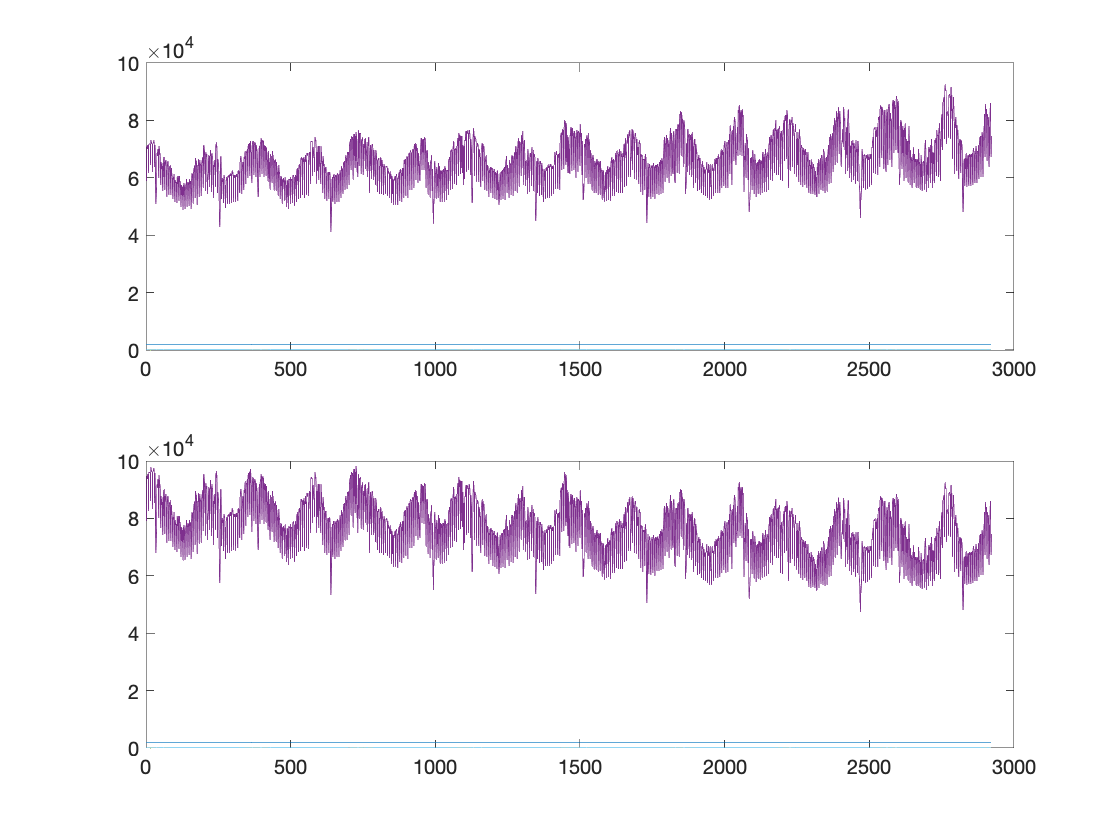

%% DRAW GRAPH
clear; clc;

load('merged_data.mat')
load('normalized_data.mat')

figure()
subplot(2,1,1)
plot(merged)
subplot(2,1,2)
plot(normalized_data)